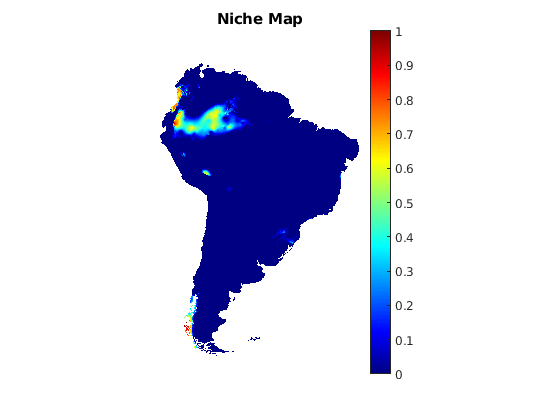

load("ModelMap.mat")
load("NicheMap.mat")

figure
geoshow(NicheMap,R,'DisplayType','surface') 
colormap jet
colorbar
axis off ; 
title("Niche Map")

NewModelMetric = MapMetric(NicheMap, ModelMap, false);
disp(NewModelMetric)

    0.9037    0.9407



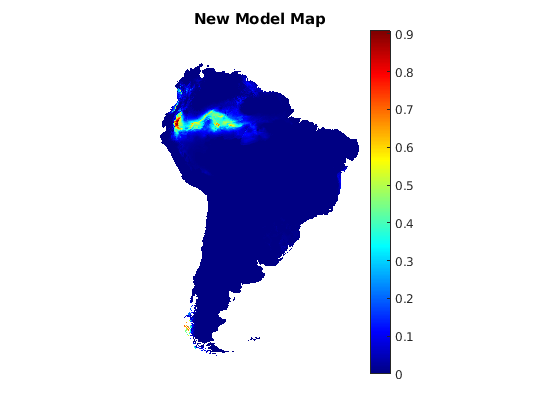

figure
geoshow(ModelMap,R,'DisplayType','surface') 
colormap jet
colorbar
axis off ; 
title("New Model Map")

Algorithm: GenSP_1_bioclim.asc


    0.9095    0.8704



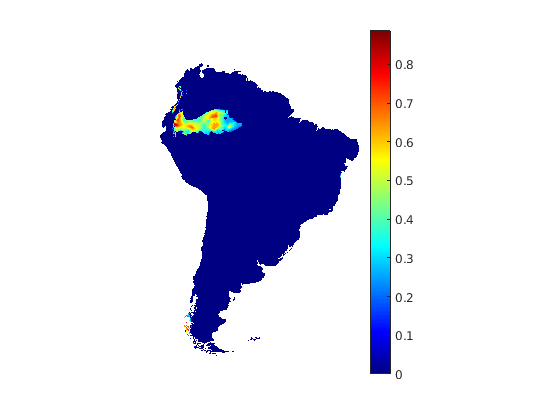

Algorithm: GenSP_1_brt.asc


    0.5584    0.8079



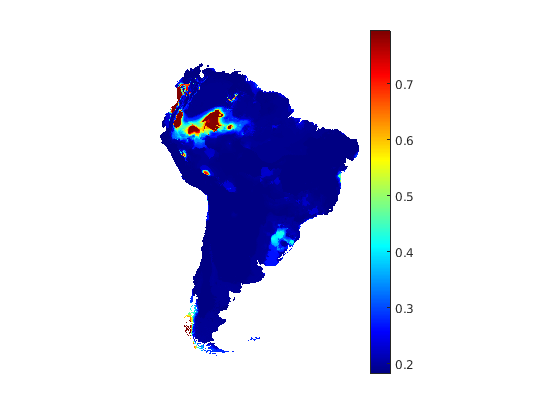

Algorithm: GenSP_1_cart.asc


    0.8495    0.9574



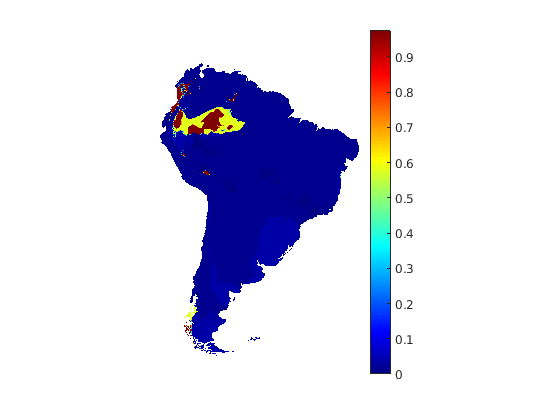

Algorithm: GenSP_1_domain.asc


    0.6042    0.7345



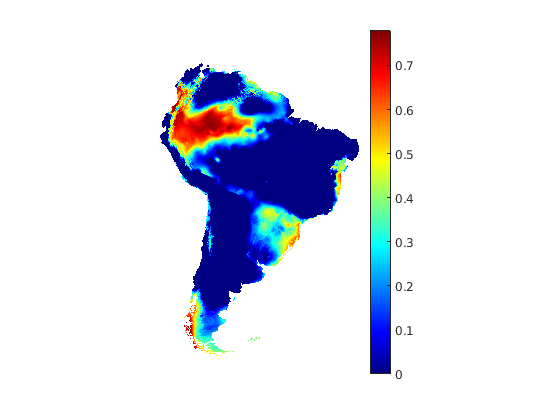

Algorithm: GenSP_1_fda.asc


    0.8276    0.9541



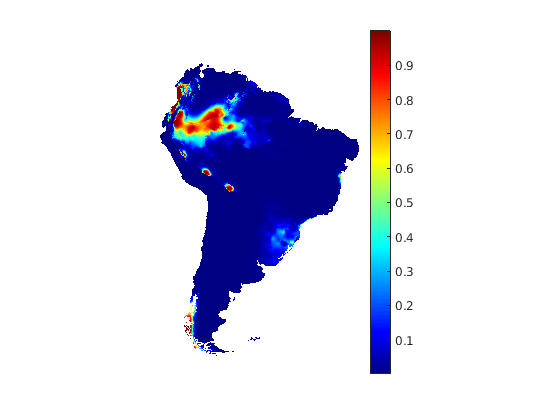

Algorithm: GenSP_1_gam.asc


    0.9107    0.9686



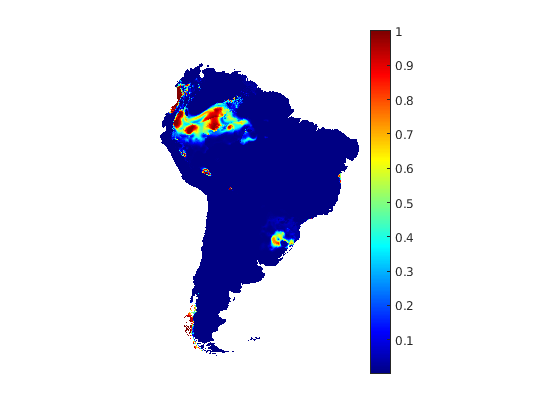

Algorithm: GenSP_1_glm.asc


    0.9019    0.9715



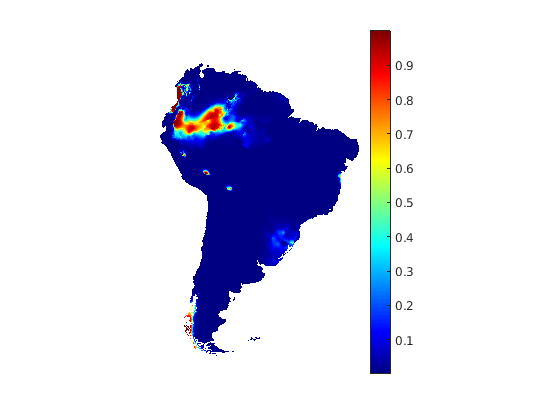

Algorithm: GenSP_1_mars.asc


    0.9058    0.9693



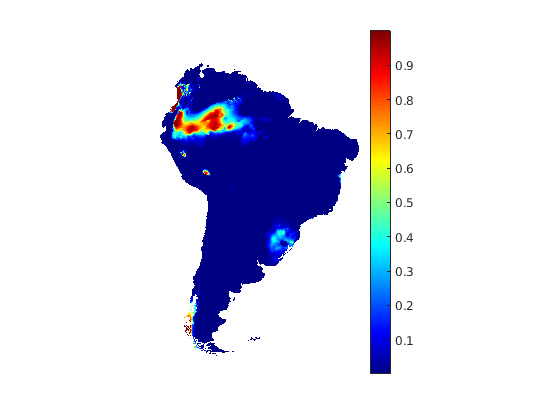

Algorithm: GenSP_1_maxent.asc


    0.8347    0.9706



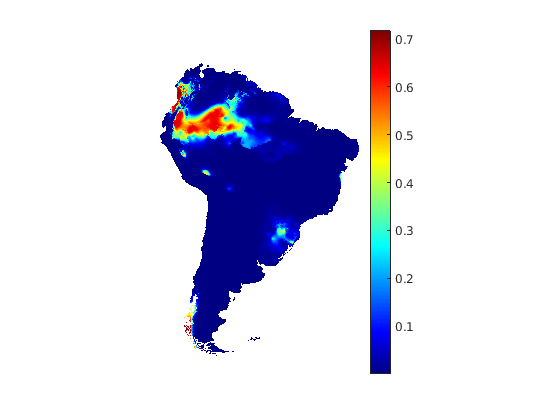

Algorithm: GenSP_1_maxlike.asc


    0.5616    0.6133



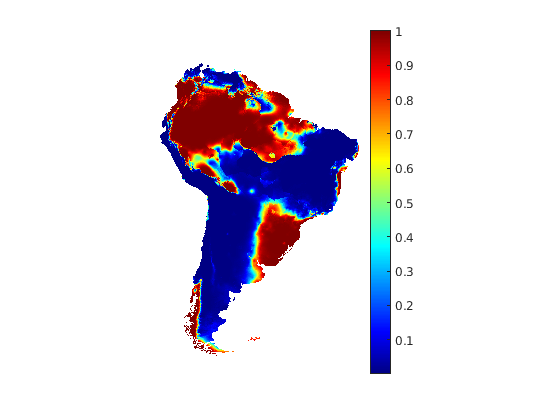

Algorithm: GenSP_1_mda.asc


    0.8879    0.9528



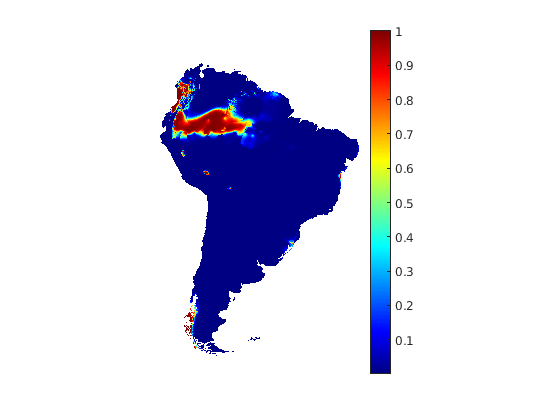

Algorithm: GenSP_1_rf.asc


    0.8191    0.9607



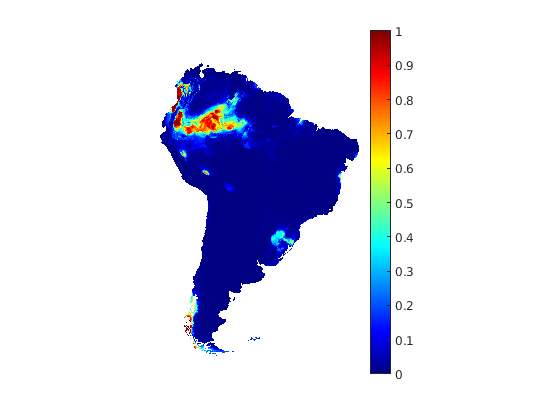

Algorithm: GenSP_1_svm.asc


    0.8497    0.9461



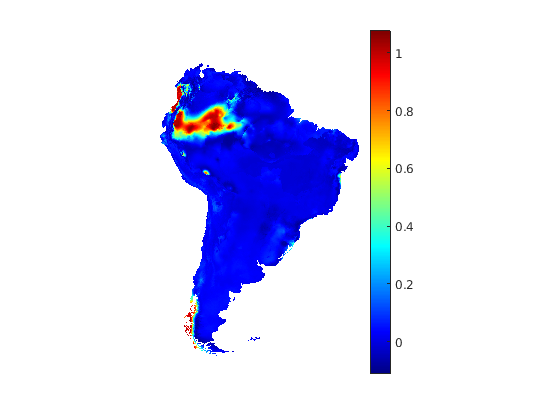

myDir ="/home/curie/MATLAB-Drive/VirtualSpecies/Prueba_Algoritmos/";
myFiles = dir(fullfile(myDir,"*.asc"));
Table=[];
for k = 1:length(myFiles)
  baseFileName(k) = convertCharsToStrings(myFiles(k).name);
  fprintf(1, 'Algorithm: %s\n', baseFileName(k));
  [ModelMap, R] =  arcgridread(baseFileName(k));
  Table(k,:) = MapMetric(NicheMap, ModelMap, false);
  disp(Table(k,:));
  figure
  geoshow(ModelMap,R,'DisplayType','surface')  
  colormap jet
  colorbar
  axis off ; 
  drawnow
end

baseFileName(end+1)="New Algorithm";
Table(end+1,:) = NewModelMetric;

[~, idx] = sort(Table);

disp("Distance")

Distance


for i=1:length(Table)
 disp(baseFileName(idx(i,2))+": "+num2str(Table(idx(i,2),2)))
end

GenSP_1_maxlike.asc: 0.61326
GenSP_1_domain.asc: 0.73449
GenSP_1_brt.asc: 0.80792
GenSP_1_bioclim.asc: 0.87037
New Algorithm: 0.94067
GenSP_1_svm.asc: 0.94612
GenSP_1_mda.asc: 0.95284
GenSP_1_fda.asc: 0.95413
GenSP_1_cart.asc: 0.95741
GenSP_1_rf.asc: 0.9607
GenSP_1_gam.asc: 0.96861
GenSP_1_mars.asc: 0.96933
GenSP_1_maxent.asc: 0.97058
GenSP_1_glm.asc: 0.97153


disp("Area")

Area


for i=1:length(Table)
 disp(baseFileName(idx(i,1))+": "+num2str(Table(idx(i,1),1)))
end

GenSP_1_brt.asc: 0.55837
GenSP_1_maxlike.asc: 0.56157
GenSP_1_domain.asc: 0.60415
GenSP_1_rf.asc: 0.81909
GenSP_1_fda.asc: 0.82757
GenSP_1_maxent.asc: 0.83473
GenSP_1_cart.asc: 0.84953
GenSP_1_svm.asc: 0.84971
GenSP_1_mda.asc: 0.88788
GenSP_1_glm.asc: 0.90186
New Algorithm: 0.90368
GenSP_1_mars.asc: 0.9058
GenSP_1_bioclim.asc: 0.90953
GenSP_1_gam.asc: 0.91074
